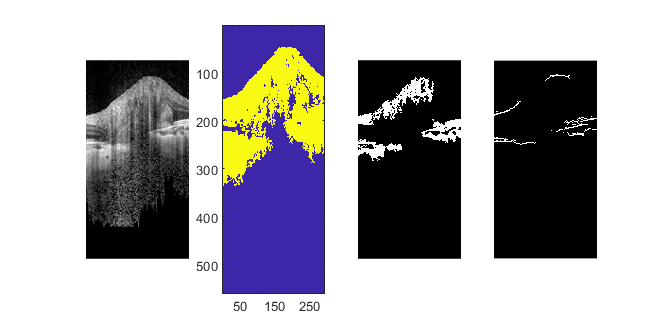

current_path = pwd;
cd D:/OCT/newdata/patient_001/left1(micron)_png/yz;
name = num2str(288);
I = imread(strcat(name,'.png'));
I_tag = imread(strcat("tag_try_2\",name,".png"));
figure();
set(gcf, 'Position',  [0, 0, 800, 400])
hold on;
f1 = subplot(1,4,1); % fig 1 \|/
imshow(I);
f2 = subplot(1,4,2); % fig 2
I_f2 = I; I_f2(I_f2<prctile(I_f2,70))=0;
I_f2 = bwareaopen(I_f2, 1000);
% I_f2 = I; I_f2(I_f2<prctile(I_f2,33))=0;
% I_f2 = diff(I,1); 
% I_f2 = bwareaopen(I_f2,8000);
imagesc(I_f2);
f_3 = subplot(1,4,3); % fig 3
I_f3 = I; I_f3(I_f3<prctile(I_f3,90))=0;
I_f3 = bwareaopen(I_f3, 1000);
imshow(I_f3);
f4 = subplot(1,4,4); % fig 4
I_f4 = diff(I,2); 
% I_f4 = I_f4*10; I_f4(I_f4>255) = 255;
I_f4(I_f4<prctile(I_f4,85))=0;
I_f4 = bwareaopen(I_f4, 250);
imshow(I_f4);
hold off;

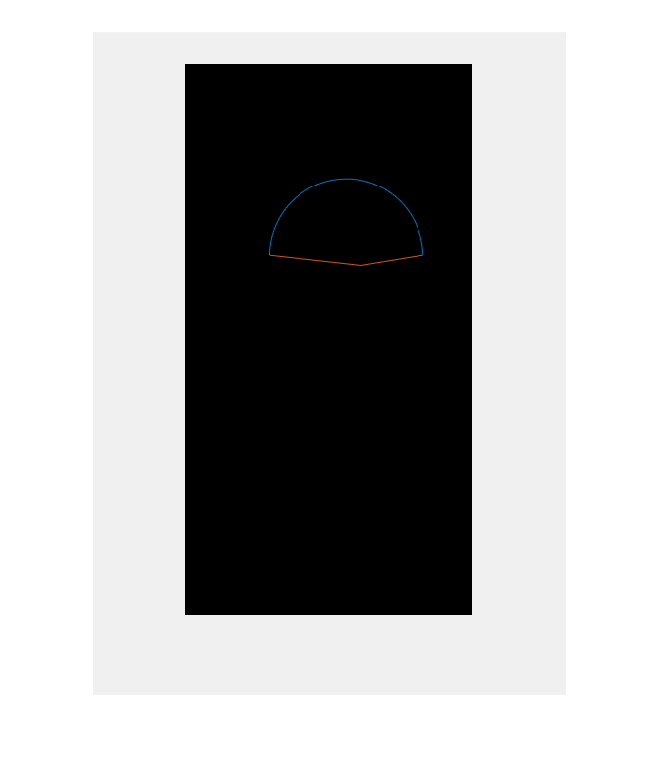

% P1. Points of Interest
% Point 1
row = find(I_f3(:,end),1,'last');
cc8 = bwconncomp(I_f3,8);
L8 = labelmatrix(cc8); group = L8(row,size(L8,2));
[row_p1,col_p1] = find(L8==group,1,'first');
L8_3 = L8;
% Point 2
cc8 = bwconncomp(I_f4,8);
L8 = labelmatrix(cc8);
row_seq = find(L8(:,end)~=0); v = L8(row_seq,end); row_ind = find(v~=v(1),1);
row = row_seq(row_ind);
[row_p2,col_p2] = find(L8==L8(row,size(L8,2)),1,'first');
% Point 3
col_p3 = col_p2; 
row_p3 = find(I_f2(1:row_p2-1,col_p3) & I_f2(1:row_p2-1,col_p3)~=group,1,'first');
row_p3 = round((row_p3 + row_p2)/2);
% P2. Region of Interest
% Semi-circle
%  Center of circle
A = ((row_p3-row_p1)*row_p2+(col_p3-col_p1)*col_p2)/(row_p3-row_p1);
B = -(col_p3-col_p1)/(row_p3-row_p1);
C = A - row_p1; D = (row_p2-row_p1)^2+(col_p2-col_p1)^2;
col_p4 = (C^2+col_p1^2-D)/(B^2+1)/col_p2; row_p4 = A + B*col_p4;
%  Plot Semi-circle
r = sqrt((col_p4-col_p3)^2+(row_p4-row_p3)^2);
th = 0.5*pi:pi/50:1.5*pi;
row_unit = r * cos(th) + row_p4;
col_unit = r * sin(th) + col_p4;
f5 = figure(5);
f5.Visible = 'off';
imshow(I*0);
hold on;
semi = plot(col_unit,row_unit);
% Zigzag
row_p5 = r * cos(th(end)) + row_p4; col_p5 = r * sin(th(end)) + col_p4;
zig = plot([col_p5,col_p1,col_p2,r * sin(th(1)) + col_p4],[row_p5,row_p1,row_p2,r * cos(th(1)) + row_p4]);
hold off;
F = getframe(gcf);
[X,MAP] = frame2im(F); % image to matrix data
figure(6);
imshow(X);

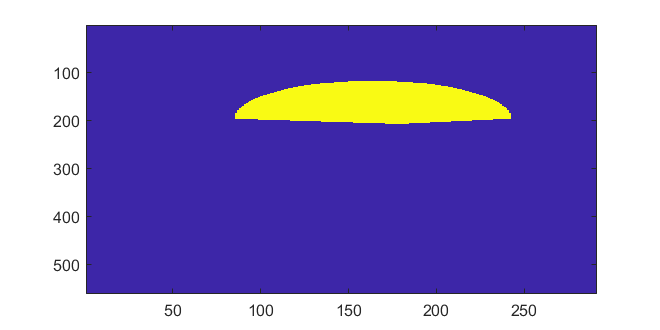

X_f = imfill(X(33:593,95:385,2));
X_f(X_f ~= 0) = 1;
figure(7);
imagesc(X_f);

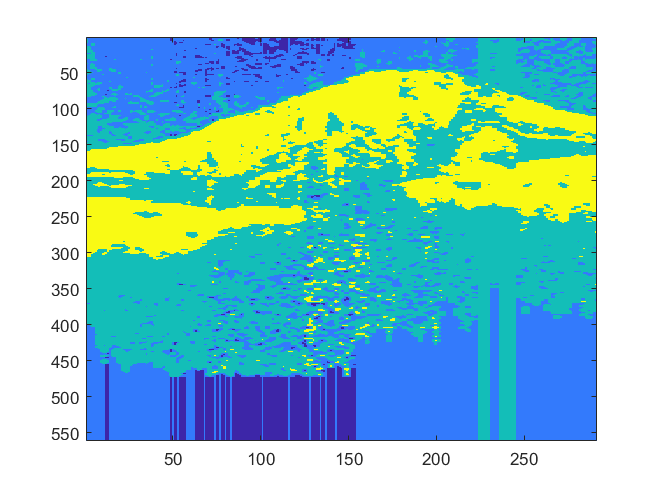

I_tmp = I;
I_tmp(I<prctile(I,20)) = 0;
I_tmp(I>=prctile(I,20) & I<prctile(I,40)) = 1;
I_tmp(I>=prctile(I,40) & I<prctile(I,60)) = 2;
I_tmp(I>=prctile(I,60) & I<prctile(I,80)) = 2;
I_tmp(I>=prctile(I,80)) = 4;
figure();
imagesc(I_tmp);

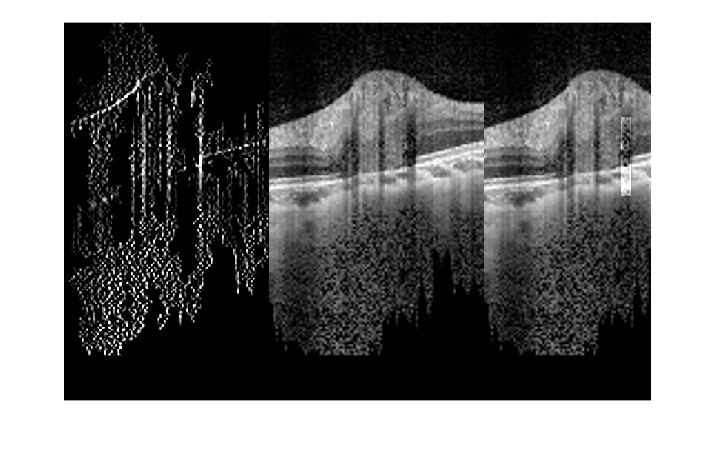

% image 442 shadow removing test
current_path = pwd;
cd D:/OCT/newdata/patient_001/left1(micron)_png/yz;
name = num2str(442);
I = imread(strcat(name,'.png'));
I_tag = imread(strcat("tag_try_2\",name,".png"));
I_right = I;
I_right(150:256,186:198)=I(150:256,186:198)*1.95;
I_left = abs(diff(I,1,2))*10;
I_left(~bwareaopen(I_left,10000)) = 0; 
imshow([I_left I I_right]);

n=1000;k=10;
for m = 197:212
    mult = 1;
    for idx = 0:k-1
        mult = mult*(n-m-idx)/(n-idx);
    end
%     fprintf("m=%d,PA=%.5f\n",m,1-mult);
    fprintf("%d& %.5f\\\\\n\\hline\n",m,1-mult);
end

197& 0.88976\\
\hline
198& 0.89114\\
\hline
199& 0.89249\\
\hline
200& 0.89384\\
\hline
201& 0.89516\\
\hline
202& 0.89647\\
\hline
203& 0.89777\\
\hline
204& 0.89905\\
\hline
205& 0.90032\\
\hline
206& 0.90158\\
\hline
207& 0.90282\\
\hline
208& 0.90404\\
\hline
209& 0.90525\\
\hline
210& 0.90645\\
\hline
211& 0.90764\\
\hline
212& 0.90881\\
\hline


n=10000;k=100;
for m = 219:236
    mult = 1;
    for idx = 0:k-1
        mult = mult*(n-m-idx)/(n-idx);
    end
%     fprintf("m=%d,PA=%.7f\n",m,1-mult);
    fprintf("%d& %.7f\\\\\n\\hline\n",m,1-mult);
end

219& 0.8919860\\
\hline
220& 0.8930903\\
\hline
221& 0.8941835\\
\hline
222& 0.8952656\\
\hline
223& 0.8963367\\
\hline
224& 0.8973970\\
\hline
225& 0.8984465\\
\hline
226& 0.8994854\\
\hline
227& 0.9005138\\
\hline
228& 0.9015318\\
\hline
229& 0.9025394\\
\hline
230& 0.9035369\\
\hline
231& 0.9045242\\
\hline
232& 0.9055016\\
\hline
233& 0.9064690\\
\hline
234& 0.9074266\\
\hline
235& 0.9083745\\
\hline
236& 0.9093128\\
\hline
